

% Reliability of information in a structure between two sessions

cd /media/DataMOBsRAIDN/PFC_InteroceptiveTuning/DecodingAnalysis
load('DataDecoding_HPC_position.mat')
Opts.ParamBinLims = [0:0.1:1];

## Recalculate the tuning curves and see if they're the same in both sessions

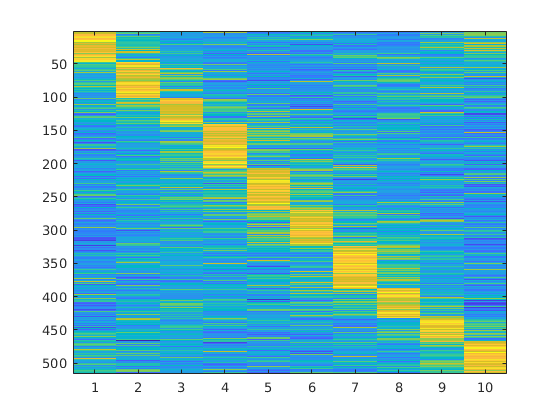

TuningAll_1 = [];
for mm = 1:length(spike_dat.Habituation_NoFreeze)
    clear Tuning_temp
    for ii = 1:length(Opts.ParamBinLims)-1
        BinsOI = find(VarOfInterest.Habituation_NoFreeze{mm}>Opts.ParamBinLims(ii) & VarOfInterest.Habituation_NoFreeze{mm}<Opts.ParamBinLims(ii+1));
        Tuning_temp(:,ii) = nanmean(spike_dat.Habituation_NoFreeze{mm}(:,BinsOI),2);
    end
    TuningAll_1 = [TuningAll_1;Tuning_temp];
end
[~,ind]=max(zscore(TuningAll_1'));
[~,ind]=sort(ind);
figure
imagesc(nanzscore(TuningAll_1(ind,:)')')

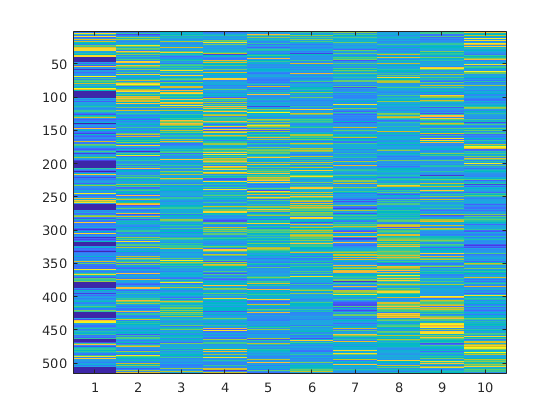


TuningAll_2 = [];
for mm = 1:length(spike_dat.Conditionning)
    clear Tuning_temp
    for ii = 1:length(Opts.ParamBinLims)-1
        BinsOI = find(VarOfInterest.Conditionning{mm}>Opts.ParamBinLims(ii) & VarOfInterest.Conditionning ...
            {mm}<Opts.ParamBinLims(ii+1));
        Tuning_temp(:,ii) = nanmean(spike_dat.Conditionning{mm}(:,BinsOI),2);
    end
    TuningAll_2 = [TuningAll_2;Tuning_temp];
end
figure
imagesc(nanzscore(TuningAll_2(ind,:)')')

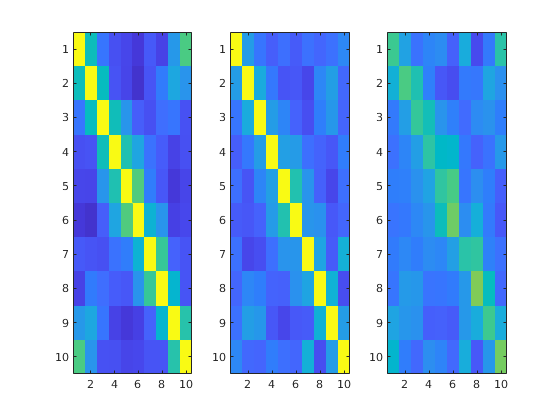


figure
subplot(131)
imagesc(corr(nanzscore(TuningAll_1')','rows','pairwise'))
caxis([-0.5 1])
subplot(132)
imagesc(corr(nanzscore(TuningAll_2')','rows','pairwise'))
caxis([-0.5 1])
subplot(133)
imagesc(corr(nanzscore(TuningAll_1')',nanzscore(TuningAll_2')','rows','pairwise'))
caxis([-0.5 1])

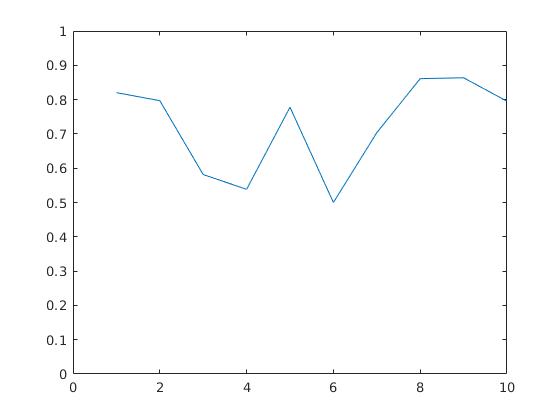

% Do the decoding on the same session
clear Data_todecode TrNumPerMouse
TuningAll_1 = [];
for mm = 1:length(spike_dat.Habituation_NoFreeze)
    clear Tuning_temp
    for ii = 1:length(Opts.ParamBinLims)-1
        BinsOI = find(VarOfInterest.Habituation_NoFreeze{mm}>Opts.ParamBinLims(ii) & VarOfInterest.Habituation_NoFreeze{mm}<Opts.ParamBinLims(ii+1));
        Tuning_temp(:,ii) = nanmean(spike_dat.Habituation_NoFreeze{mm}(:,BinsOI(1:2:end)),2);
        Data_todecode{mm}{ii} = spike_dat.Habituation_NoFreeze{mm}(:,BinsOI(2:2:end));
    end
    TuningAll_1 = [TuningAll_1;Tuning_temp];
end

for mm = 1:length(spike_dat.Conditionning)
    TrNumPerMouse(mm,:) = cellfun(@(x) size(x,2),Data_todecode{mm});
end

for ii = 1:length(Opts.ParamBinLims)-1
    TrialNumToUse = min(TrNumPerMouse(:,ii));
    Data_todecode_temp = [];
    for mm = 1:length(spike_dat.Conditionning)
        Data_todecode_temp = [Data_todecode_temp;Data_todecode{mm}{ii}(:,randperm(TrNumPerMouse(mm,ii),TrialNumToUse))];
    end
    [val,ind] = max(corr(TuningAll_1,Data_todecode_temp));
    PropCorr(ii) = nanmean(ind==ii);

end
figure
plot(PropCorr)
ylim([0 1])
xlim([0 11])

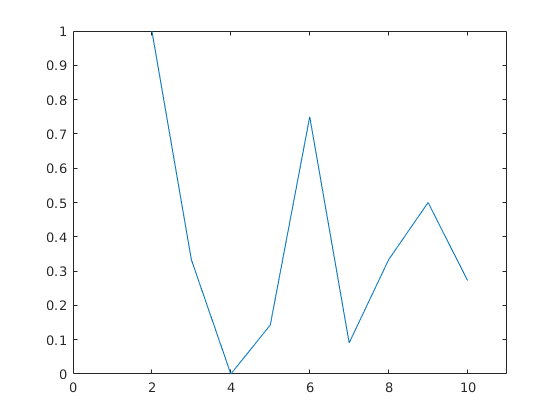

% Do the decoding on the same session
clear Data_todecode TrNumPerMouse
for mm = 1:length(spike_dat.Conditionning)
    clear Tuning_temp
    for ii = 1:length(Opts.ParamBinLims)-1
        BinsOI = find(VarOfInterest.Conditionning{mm}>Opts.ParamBinLims(ii) & VarOfInterest.Conditionning{mm}<Opts.ParamBinLims(ii+1));
        Data_todecode{mm}{ii} = spike_dat.Conditionning{mm}(:,BinsOI(2:2:end));
    end
end

for mm = 1:length(spike_dat.Conditionning)
    TrNumPerMouse(mm,:) = cellfun(@(x) size(x,2),Data_todecode{mm});
end

clear PropCorr
for ii = 1:length(Opts.ParamBinLims)-1
    TrialNumToUse = min(TrNumPerMouse(:,ii));
    Data_todecode_temp = [];
    for mm = 1:length(spike_dat.Conditionning)
        Data_todecode_temp = [Data_todecode_temp;Data_todecode{mm}{ii}(:,randperm(TrNumPerMouse(mm,ii),TrialNumToUse))];
    end
    [val,ind] = max(corr(TuningAll_1,Data_todecode_temp));
    PropCorr(ii) = nanmean(ind==ii);

end
figure
plot(PropCorr)
ylim([0 1])
xlim([0 11])